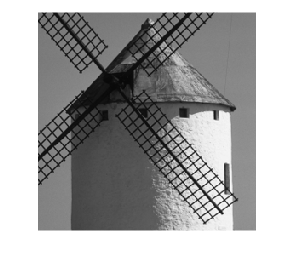

%imwrite(b11, ’b11.tif’, ’Resolution’, 150);
%Kommandot sparar bilden med upplösningen 150 dots (eller pixlar)/tum 
% i tif format
clear;
kvarn = imread('kvarn.tif');
kvarn = im2double(kvarn);
imshow(kvarn);

% 1.1 
b11 = (kvarn >= 0.5)

b11 = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

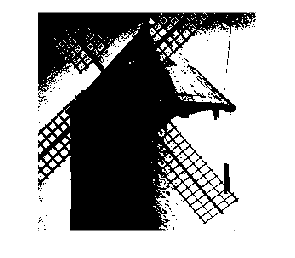

imshow(b11)

imwrite(b11, 'b11.tif', 'Resolution', 150);

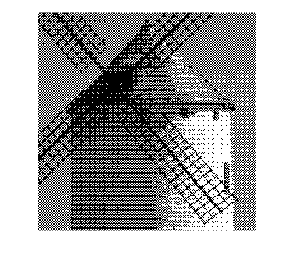

% 1.2
load('troskelmatriser.mat')
tr1 = tr1/19;
tr2 = tr2/33;
b12_tr1 = troskel(kvarn, tr1);
imshow(b12_tr1)

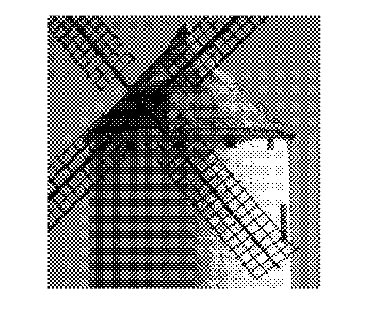

b12_tr2 = troskel(kvarn, tr2);
imshow(b12_tr2)

imwrite(b12_tr1, 'b12_tr1.tif', 'Resolution', 150);
imwrite(b12_tr2, 'b12_tr2.tif', 'Resolution', 150);